## 0. 参数设置 

clear;close all;
ROI.Cl35a = [195-15,195+15];
ROI.Cl35b = [611-15,611+15];
ROI.Cl35c = [662-15,662+15];
ROItitle.Cl35a = 'Count of 1.959MeV peak';
ROItitle.Cl35b = 'Count of 6.111MeV peak';
ROItitle.Cl35c = 'Count of 6.620MeV peak';

ROIselected = {'Cl35a','Cl35b','Cl35c'};

% 只保留ROI中被ROIselected选中的区间
nameTmp = fieldnames(ROI);
for i = 1:length(nameTmp)
    if ~ismember(nameTmp{i},ROIselected)
        ROI = rmfield(ROI,nameTmp{i});
        ROItitle = rmfield(ROItitle,nameTmp{i});
    end
end
ROI = orderfields(ROI);
ROItitle = orderfields(ROItitle);

% old code consider delete
% ROI_Cl1 = 195-15:195+15; % unit:10keV, original 195
% ROI_Cl2 = 611-15:611+15;
% ROI_Cl1 = 662-15:662+15;
% dotcloudXtitle = 'Count of 6.620MeV peak';
% dotcloudYtitle = 'Count of 6.111MeV peak';

bkgdFileName = 'Aug4-0kg-step0.01MeV-nml';
smplFileName = 'P23-1kg-step0.01MeV-nml';
energyAxis = [0.01:0.01:12]';

outlierThresh = 2; % 几倍标准差以外算离群点

## 1. 导入能谱及预处理

### 1.1 导入

[bkgd,smpl] = ...
    loadSpecSeq(bkgdFileName,smplFileName);

### 1.2 预处理

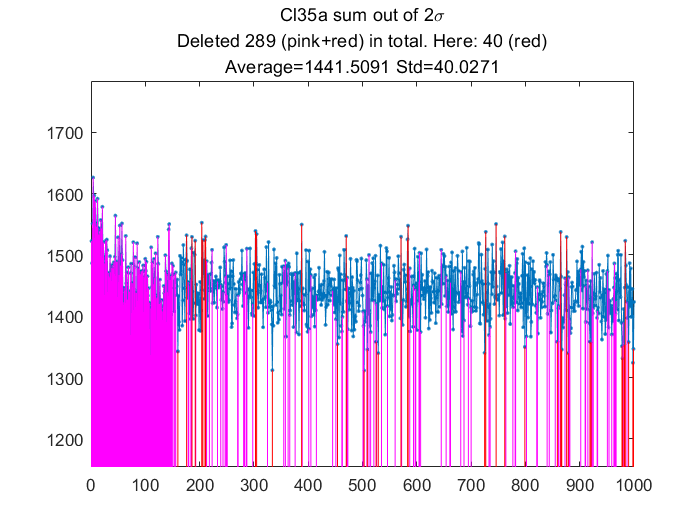

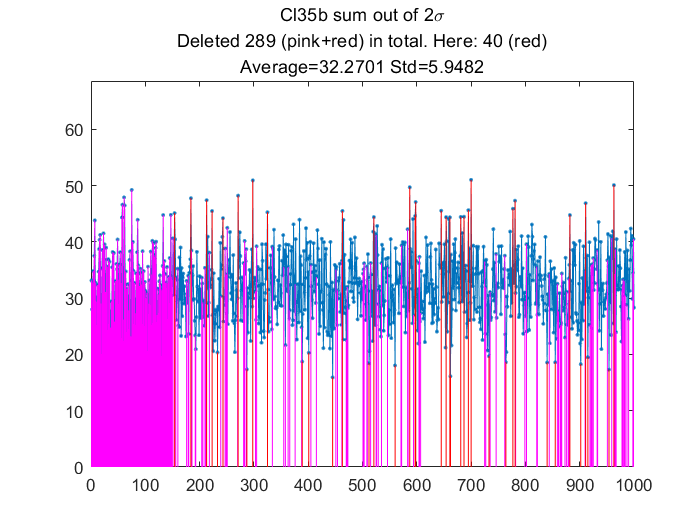

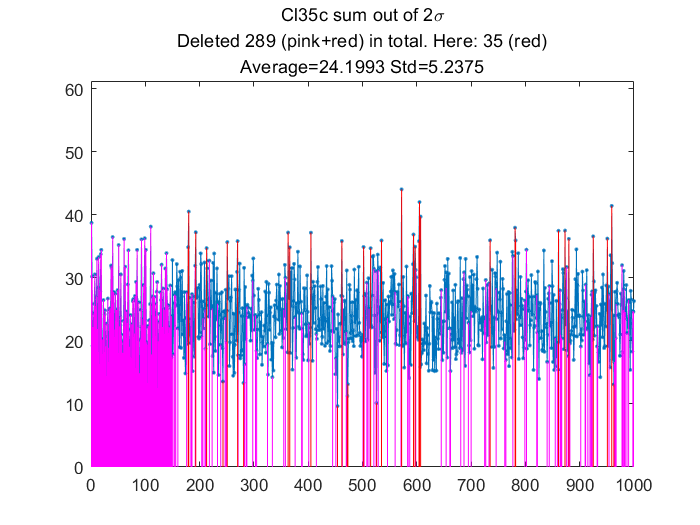

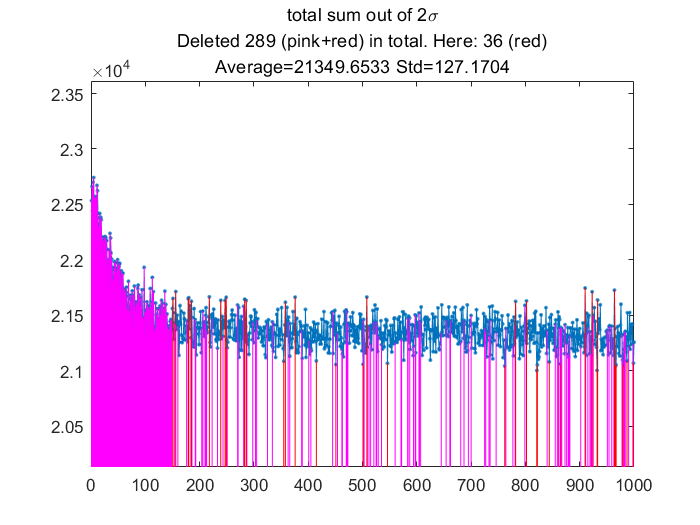

bkgd0=bkgd;smpl0=smpl;
% 刚开始剂量高，需删除
stableTime = 150; % 时间序列的第几个点起稳定
[bkgd,delCh,delSeg] = delOutlier(bkgd,150,ROI,2,1);

[smpl,delCh,delSeg] = delOutlier(smpl,150,ROI,2,1);

% 本底谱离群点
seq(1,:) = sum(bkgd(:,stableTime:end),1);
seq(2,:) = sum(bkgd(ROI_Cl1,stableTime:end),1);
seq(3,:) = sum(bkgd(ROI_Cl2,stableTime:end),1);

delCh = [];
for i = 1:size(seq,1)
    thisSeq = seq(i,:);
    delCh = [delCh,find(thisSeq<mean(thisSeq)-outlierThresh*std(thisSeq,0))];
    delCh = [delCh,find(thisSeq>mean(thisSeq)+outlierThresh*std(thisSeq,0))];
end
delCh = delCh + stableTime - 1;

% 展示本底谱删除的点
if stableTime~=1
    delCh = [delCh,1:stableTime-1];
end
delCh = unique(delCh);
bkgd0=bkgd;
bkgd0(:,delCh) = [];

figure;
subplot(311);
plot(1:size(bkgd,2),sum(bkgd,1),'.-');hold on;
title({'Deleted 1s spec from totalsum';['All average=',num2str(mean(sum(bkgd,1))),' std=',num2str(std(sum(bkgd,1),0))]; ...
    ['Selected average=',num2str(mean(sum(bkgd0,1))),' std=',num2str(std(sum(bkgd0,1),0))]});
for i = 1:size(delCh,2)
    plot([delCh(i),delCh(i)],[0,sum(bkgd(:,delCh(i)),1)],'r-');
end

subplot(312);
plot(1:size(bkgd,2),sum(bkgd(ROI_Cl1,:),1),'.-');hold on;
title({'Deleted 1s spec from Cl1sum';['All average=',num2str(mean(sum(bkgd(ROI_Cl1,:),1))),' std=',num2str(std(sum(bkgd(ROI_Cl1,:),1),0))]; ...
    ['Selected average=',num2str(mean(sum(bkgd0(ROI_Cl1,:),1))),' std=',num2str(std(sum(bkgd0(ROI_Cl1,:),1),0))]});
for i = 1:size(delCh,2)
    plot([delCh(i),delCh(i)],[0,sum(bkgd(ROI_Cl1,delCh(i)),1)],'r-');
end

subplot(313);
plot(1:size(bkgd,2),sum(bkgd(ROI_Cl2,:),1),'.-');hold on;
title({'Deleted 1s spec from Cl2sum';['All average=',num2str(mean(sum(bkgd(ROI_Cl2,:),1))),' std=',num2str(std(sum(bkgd(ROI_Cl2,:),1),0))]; ...
    ['Selected average=',num2str(mean(sum(bkgd0(ROI_Cl2,:),1))),' std=',num2str(std(sum(bkgd0(ROI_Cl2,:),1),0))]});
for i = 1:size(delCh,2)
    plot([delCh(i),delCh(i)],[0,sum(bkgd(ROI_Cl2,delCh(i)),1)],'r-');
end
set(gcf,'position',[0,0,2000,1800]);
disp(['本底谱共删除：',num2str(size(delCh,2)),'点，稳定前：',num2str(stableTime-1), ...
    '点，离群点：',num2str(size(delCh,2)-stableTime+1)]);
figure;
[y,x]=hist(sum(bkgd,1),0:1e2:5e4);
plot(x,y,'r.-');hold on;
[y,x]=hist(sum(bkgd0,1),0:1e2:5e4);
plot(x,y,'b.-');
title('Count rate distribution of bkgd full spectra');
xlabel('Count rate(cps)')
ylabel('Frequency (/100cps)');
legend('all','select');

bkgd(:,delCh) = [];clearvars bkgd0;


% 样品谱离群点
seq=[];
seq(1,:) = sum(smpl(:,stableTime:end),1);
seq(2,:) = sum(smpl(ROI_Cl1,stableTime:end),1);
seq(3,:) = sum(smpl(ROI_Cl2,stableTime:end),1);
seqSeg = zeros(size(seq,1),1); % seqSeg做分割点的左开右闭区间为该序列离群点
delCh = [];
for i = 1:size(seq,1)
    thisSeq = seq(i,:);
    delCh = [delCh,find(thisSeq<mean(thisSeq)-outlierThresh*std(thisSeq,0))];
    delCh = [delCh,find(thisSeq>mean(thisSeq)+outlierThresh*std(thisSeq,0))];
    seqSeg(i,1) = size(delCh,2);
end
delCh = delCh + stableTime - 1;
seqSeg = [stableTime;seqSeg+stableTime-1];
% 展示样品谱删除的点并删除
if stableTime~=1
    delCh = [delCh,1:stableTime-1];
end
delCh = unique(delCh);
smpl0=smpl;
smpl0(:,delCh) = [];

figure;
subplot(311);
plot(1:size(smpl,2),sum(smpl,1),'.-');hold on;
title({'Deleted(red) 1s spec from totalsum';['All average=',num2str(mean(sum(smpl,1))),' std=',num2str(std(sum(smpl,1),0))]; ...
    ['Selected average=',num2str(mean(sum(smpl0,1))),' std=',num2str(std(sum(smpl0,1),0))]});
for i = 1:size(delCh,2)
    plot([delCh(i),delCh(i)],[0,sum(smpl(:,delCh(i)),1)],'r-');
end

subplot(312);
plot(1:size(smpl,2),sum(smpl(ROI_Cl1,:),1),'.-');hold on;
title({'Deleted(red) 1s spec from Cl1sum';['All average=',num2str(mean(sum(smpl(ROI_Cl1,:),1))),' std=',num2str(std(sum(smpl(ROI_Cl1,:),1),0))]; ...
    ['Selected average=',num2str(mean(sum(smpl0(ROI_Cl1,:),1))),' std=',num2str(std(sum(smpl0(ROI_Cl1,:),1),0))]});
for i = 1:size(delCh,2)
    plot([delCh(i),delCh(i)],[0,sum(smpl(ROI_Cl1,delCh(i)),1)],'r-');
end

subplot(313);
plot(1:size(smpl,2),sum(smpl(ROI_Cl2,:),1),'.-');hold on;
title({'Deleted(red) 1s spec from Cl2sum';['All average=',num2str(mean(sum(smpl(ROI_Cl2,:),1))),' std=',num2str(std(sum(smpl(ROI_Cl2,:),1),0))]; ...
    ['Selected average=',num2str(mean(sum(smpl0(ROI_Cl2,:),1))),' std=',num2str(std(sum(smpl0(ROI_Cl2,:),1),0))]});
for i = 1:size(delCh,2)
    plot([delCh(i),delCh(i)],[0,sum(smpl(ROI_Cl2,delCh(i)),1)],'r-');
end
set(gcf,'position',[0,0,2000,1800]);
disp(['样品谱共删除：',num2str(size(delCh,2)),'点，稳定前：',num2str(stableTime-1), ...
    '点，离群点：',num2str(size(delCh,2)-stableTime+1)]);
figure;
[y,x]=hist(sum(smpl,1),0:1e2:5e4);
plot(x,y,'r.-');hold on;
[y,x]=hist(sum(smpl0,1),0:1e2:5e4);
plot(x,y,'b.-');
title('Count rate distribution of smpl full spectra');
xlabel('Count rate(cps)')
ylabel('Frequency (/100cps)');
legend('all','select');
smpl(:,delCh) = [];clearvars smpl0;


### 1.3 非异常能谱加和展示

figure;
semilogy(energyAxis,[sum(bkgd,2),sum(smpl,2)]/size(bkgd,2));hold on;
xlabel('Energy(MeV)');
ylabel(['Count rate(cps/',num2str(1000*(energyAxis(2)-energyAxis(1))),'keV)']);
legend('bkgd','smpl');
xlim([0 12]);ylim([1e-3 1e3]);
title('bkgd & sample');
hold off;

## 2. 点云图

### 2.1 1s

cloud1s.bkgdCl1 = sum(bkgd(ROI_Cl1,:),1)';
cloud1s.bkgdCl2 = sum(bkgd(ROI_Cl2,:),1)';
cloud1s.smplCl1 = sum(smpl(ROI_Cl1,:),1)';
cloud1s.smplCl2 = sum(smpl(ROI_Cl2,:),1)';
figure;
plot(cloud1s.bkgdCl1,cloud1s.bkgdCl2,'.');hold on;
plot(cloud1s.smplCl1,cloud1s.smplCl2,'x');
xlabel(dotcloudXtitle);ylabel(dotcloudYtitle);
[FOM,~,centers,dis,sigma_bkgd,sigma_smpl]=cclFoM([cloud1s.bkgdCl1,cloud1s.bkgdCl2],[cloud1s.smplCl1,cloud1s.smplCl2]);
plot(centers(1,1),centers(1,2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','g');% 绿色的本底中心
plot(centers(2,1),centers(2,2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','m');% 粉色毒品中心
% title({['FoM=',num2str(FOM),',d=',num2str(dis),];['\sigma_b_k_g_d=',num2str(sigma_bkgd), ...
%     ', \sigma_s_m_p_l=',num2str(sigma_smpl)]});
legend('0kg drug','1kg drug','center(0kg)','center(1kg)','Location','northwest');
axis square;
hold off;

### 2.2 2s

measureTime = 2; bkgdtmpl = [];smpltmpl=[];
for i = 1:floor(size(bkgd,2)/measureTime)
    bkgdtmpl = [bkgdtmpl,sum(bkgd(:,measureTime*(i-1)+1:measureTime*i),2)];
end
for i = 1:floor(size(smpl,2)/measureTime)
    smpltmpl = [smpltmpl,sum(smpl(:,measureTime*(i-1)+1:measureTime*i),2)];
end

cloud2s.bkgdCl1 = sum(bkgdtmpl(ROI_Cl1,:),1)';
cloud2s.bkgdCl2 = sum(bkgdtmpl(ROI_Cl2,:),1)';
cloud2s.smplCl1 = sum(smpltmpl(ROI_Cl1,:),1)';
cloud2s.smplCl2 = sum(smpltmpl(ROI_Cl2,:),1)';
figure;
plot(cloud2s.bkgdCl1,cloud2s.bkgdCl2,'.');hold on;
plot(cloud2s.smplCl1,cloud2s.smplCl2,'x');
xlabel(dotcloudXtitle);ylabel(dotcloudYtitle);
[FOM,~,centers,dis,sigma_bkgd,sigma_smpl]=cclFoM([cloud2s.bkgdCl1,cloud2s.bkgdCl2],[cloud2s.smplCl1,cloud2s.smplCl2]);
plot(centers(1,1),centers(1,2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','g');% 绿色的本底中心
plot(centers(2,1),centers(2,2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','m');% 粉色毒品中心
title({['FoM=',num2str(FOM),',d=',num2str(dis),];['\sigma_b_k_g_d=',num2str(sigma_bkgd), ...
    ', \sigma_s_m_p_l=',num2str(sigma_smpl)]});
legend('bkgd','smpl','bkgd-center','smpl-center','Location','northwest');
axis square;
hold off;

### 2.3 5s

measureTime = 5; bkgdtmpl = [];smpltmpl=[];
for i = 1:floor(size(bkgd,2)/measureTime)
    bkgdtmpl = [bkgdtmpl,sum(bkgd(:,measureTime*(i-1)+1:measureTime*i),2)];
end
for i = 1:floor(size(smpl,2)/measureTime)
    smpltmpl = [smpltmpl,sum(smpl(:,measureTime*(i-1)+1:measureTime*i),2)];
end
cloud5s.bkgdCl1 = sum(bkgdtmpl(ROI_Cl1,:),1)';
cloud5s.bkgdCl2 = sum(bkgdtmpl(ROI_Cl2,:),1)';
cloud5s.smplCl1 = sum(smpltmpl(ROI_Cl1,:),1)';
cloud5s.smplCl2 = sum(smpltmpl(ROI_Cl2,:),1)';
figure;
plot(cloud5s.bkgdCl1,cloud5s.bkgdCl2,'.');hold on;
plot(cloud5s.smplCl1,cloud5s.smplCl2,'x');
xlabel(dotcloudXtitle);ylabel(dotcloudYtitle);
[FOM,~,centers,dis,sigma_bkgd,sigma_smpl]=cclFoM([cloud5s.bkgdCl1,cloud5s.bkgdCl2],[cloud5s.smplCl1,cloud5s.smplCl2]);
plot(centers(1,1),centers(1,2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','g');% 绿色的本底中心
plot(centers(2,1),centers(2,2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','m');% 粉色毒品中心
% title({['FoM=',num2str(FOM),',d=',num2str(dis),];['\sigma_b_k_g_d=',num2str(sigma_bkgd), ...
%     ', \sigma_s_m_p_l=',num2str(sigma_smpl)]});
legend('0kg drug','1kg drug','center(0kg)','center(1kg)','Location','northwest');
axis square;
hold off;

### 2.4 10s

measureTime = 10; bkgdtmpl = [];smpltmpl=[];
for i = 1:floor(size(bkgd,2)/measureTime)
    bkgdtmpl = [bkgdtmpl,sum(bkgd(:,measureTime*(i-1)+1:measureTime*i),2)];
end
for i = 1:floor(size(smpl,2)/measureTime)
    smpltmpl = [smpltmpl,sum(smpl(:,measureTime*(i-1)+1:measureTime*i),2)];
end
cloud10s.bkgdCl1 = sum(bkgdtmpl(ROI_Cl1,:),1)';
cloud10s.bkgdCl2 = sum(bkgdtmpl(ROI_Cl2,:),1)';
cloud10s.smplCl1 = sum(smpltmpl(ROI_Cl1,:),1)';
cloud10s.smplCl2 = sum(smpltmpl(ROI_Cl2,:),1)';
figure;
plot(cloud10s.bkgdCl1,cloud10s.bkgdCl2,'.','MarkerSize',10);hold on;
plot(cloud10s.smplCl1,cloud10s.smplCl2,'x','MarkerSize',10);
xlabel(dotcloudXtitle);ylabel(dotcloudYtitle);
[FOM,~,centers,dis,sigma_bkgd,sigma_smpl]=cclFoM([cloud10s.bkgdCl1,cloud10s.bkgdCl2],[cloud10s.smplCl1,cloud10s.smplCl2]);
plot(centers(1,1),centers(1,2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','g');% 绿色的本底中心
plot(centers(2,1),centers(2,2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','m');% 粉色毒品中心
% title({['FoM=',num2str(FOM),',d=',num2str(dis),];['\sigma_b_k_g_d=',num2str(sigma_bkgd), ...
%     ', \sigma_s_m_p_l=',num2str(sigma_smpl)]});
legend('0kg drug','1kg drug','center(0kg)','center(1kg)','Location','northwest');
axis square;
hold off;

### 2.5 30s

measureTime = 30; bkgdtmpl = [];smpltmpl=[];
for i = 1:floor(size(bkgd,2)/measureTime)
    bkgdtmpl = [bkgdtmpl,sum(bkgd(:,measureTime*(i-1)+1:measureTime*i),2)];
end
for i = 1:floor(size(smpl,2)/measureTime)
    smpltmpl = [smpltmpl,sum(smpl(:,measureTime*(i-1)+1:measureTime*i),2)];
end
cloud30s.bkgdCl1 = sum(bkgdtmpl(ROI_Cl1,:),1)';
cloud30s.bkgdCl2 = sum(bkgdtmpl(ROI_Cl2,:),1)';
cloud30s.smplCl1 = sum(smpltmpl(ROI_Cl1,:),1)';
cloud30s.smplCl2 = sum(smpltmpl(ROI_Cl2,:),1)';
figure;
plot(cloud30s.bkgdCl1,cloud30s.bkgdCl2,'.');hold on;
plot(cloud30s.smplCl1,cloud30s.smplCl2,'x');
xlabel(dotcloudXtitle);ylabel(dotcloudYtitle);
[FOM,~,centers,dis,sigma_bkgd,sigma_smpl]=cclFoM([cloud30s.bkgdCl1,cloud30s.bkgdCl2],[cloud30s.smplCl1,cloud30s.smplCl2]);
plot(centers(1,1),centers(1,2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','g');% 绿色的本底中心
plot(centers(2,1),centers(2,2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','m');% 粉色毒品中心
title({['FoM=',num2str(FOM),',d=',num2str(dis),];['\sigma_b_k_g_d=',num2str(sigma_bkgd), ...
    ', \sigma_s_m_p_l=',num2str(sigma_smpl)]});
legend('bkgd','smpl','bkgd-center','smpl-center','Location','northwest');
axis square;
hold off;

### 2.6 60s

measureTime = 60; bkgdtmpl = [];smpltmpl=[];
for i = 1:floor(size(bkgd,2)/measureTime)
    bkgdtmpl = [bkgdtmpl,sum(bkgd(:,measureTime*(i-1)+1:measureTime*i),2)];
end
for i = 1:floor(size(smpl,2)/measureTime)
    smpltmpl = [smpltmpl,sum(smpl(:,measureTime*(i-1)+1:measureTime*i),2)];
end
cloud60s.bkgdCl1 = sum(bkgdtmpl(ROI_Cl1,:),1)';
cloud60s.bkgdCl2 = sum(bkgdtmpl(ROI_Cl2,:),1)';
cloud60s.smplCl1 = sum(smpltmpl(ROI_Cl1,:),1)';
cloud60s.smplCl2 = sum(smpltmpl(ROI_Cl2,:),1)';
figure;
plot(cloud60s.bkgdCl1,cloud60s.bkgdCl2,'.');hold on;
plot(cloud60s.smplCl1,cloud60s.smplCl2,'x');
xlabel(dotcloudXtitle);ylabel(dotcloudYtitle);
[FOM,~,centers,dis,sigma_bkgd,sigma_smpl]=cclFoM([cloud60s.bkgdCl1,cloud60s.bkgdCl2],[cloud60s.smplCl1,cloud60s.smplCl2]);
plot(centers(1,1),centers(1,2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','g');% 绿色的本底中心
plot(centers(2,1),centers(2,2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','m');% 粉色毒品中心
title({['FoM=',num2str(FOM),',d=',num2str(dis),];['\sigma_b_k_g_d=',num2str(sigma_bkgd), ...
    ', \sigma_s_m_p_l=',num2str(sigma_smpl)]});
legend('bkgd','smpl','bkgd-center','smpl-center','Location','northwest');
axis square;
hold off;

## 3. 计算最优投影方向

### 3.1 1s谱最优投影方向

## 4. ROC曲线

### 4.1 计算ROC

#### 4.1.1 1s谱ROC曲线

centerbkgd1s = [mean(cloud1s.bkgdCl1),mean(cloud1s.bkgdCl2)];
centersmpl1s = [mean(cloud1s.smplCl1),mean(cloud1s.smplCl2)];
% 以bkgd点云投影中心作为index=0;
[~,bkgdIndex1s,~,~,~] = pointShadow([cloud1s.bkgdCl1,cloud1s.bkgdCl2],centerbkgd1s,centersmpl1s);
[~,smplIndex1s,~,~,~] = pointShadow([cloud1s.smplCl1,cloud1s.smplCl2],centerbkgd1s,centersmpl1s);
roc1s = myROC(bkgdIndex1s,smplIndex1s,1000);

#### 4.1.2 2s谱ROC曲线

centerbkgd2s = [mean(cloud2s.bkgdCl1),mean(cloud2s.bkgdCl2)];
centersmpl2s = [mean(cloud2s.smplCl1),mean(cloud2s.smplCl2)];
% 以bkgd点云投影中心作为index=0;
[~,bkgdIndex2s,~,~,~] = pointShadow([cloud2s.bkgdCl1,cloud2s.bkgdCl2],centerbkgd2s,centersmpl2s);
[~,smplIndex2s,~,~,~] = pointShadow([cloud2s.smplCl1,cloud2s.smplCl2],centerbkgd2s,centersmpl2s);
roc2s = myROC(bkgdIndex2s,smplIndex2s,1000);

#### 4.1.3 5s谱ROC曲线

centerbkgd5s = [mean(cloud5s.bkgdCl1),mean(cloud5s.bkgdCl2)];
centersmpl5s = [mean(cloud5s.smplCl1),mean(cloud5s.smplCl2)];
% 以bkgd点云投影中心作为index=0;
[~,bkgdIndex5s,~,~,~] = pointShadow([cloud5s.bkgdCl1,cloud5s.bkgdCl2],centerbkgd5s,centersmpl5s);
[~,smplIndex5s,~,~,~] = pointShadow([cloud5s.smplCl1,cloud5s.smplCl2],centerbkgd5s,centersmpl5s);
roc5s = myROC(bkgdIndex5s,smplIndex5s,1000);

#### 4.1.4 10s谱ROC曲线

centerbkgd10s = [mean(cloud10s.bkgdCl1),mean(cloud10s.bkgdCl2)];
centersmpl10s = [mean(cloud10s.smplCl1),mean(cloud10s.smplCl2)];
% 以bkgd点云投影中心作为index=0;
[~,bkgdIndex10s,~,~,~] = pointShadow([cloud10s.bkgdCl1,cloud10s.bkgdCl2],centerbkgd10s,centersmpl10s);
[~,smplIndex10s,~,~,~] = pointShadow([cloud10s.smplCl1,cloud10s.smplCl2],centerbkgd10s,centersmpl10s);
roc10s = myROC(bkgdIndex10s,smplIndex10s,1000);

#### 4.1.5 30s谱ROC曲线

centerbkgd30s = [mean(cloud30s.bkgdCl1),mean(cloud30s.bkgdCl2)];
centersmpl30s = [mean(cloud30s.smplCl1),mean(cloud30s.smplCl2)];
% 以bkgd点云投影中心作为index=0;
[~,bkgdIndex30s,~,~,~] = pointShadow([cloud30s.bkgdCl1,cloud30s.bkgdCl2],centerbkgd30s,centersmpl30s);
[~,smplIndex30s,~,~,~] = pointShadow([cloud30s.smplCl1,cloud30s.smplCl2],centerbkgd30s,centersmpl30s);
roc30s = myROC(bkgdIndex30s,smplIndex30s,1000);

#### 4.1.6 60s谱ROC曲线

centerbkgd60s = [mean(cloud60s.bkgdCl1),mean(cloud60s.bkgdCl2)];
centersmpl60s = [mean(cloud60s.smplCl1),mean(cloud60s.smplCl2)];
% 以bkgd点云投影中心作为index=0;
[~,bkgdIndex60s,~,~,~] = pointShadow([cloud60s.bkgdCl1,cloud60s.bkgdCl2],centerbkgd60s,centersmpl60s);
[~,smplIndex60s,~,~,~] = pointShadow([cloud60s.smplCl1,cloud60s.smplCl2],centerbkgd60s,centersmpl60s);
roc60s = myROC(bkgdIndex60s,smplIndex60s,1000);


### 4.2 ROC画图

lineWidth = 2;fontSize = 12;
figure;
plot(roc1s(:,2),roc1s(:,1),':','LineWidth',lineWidth);hold on;
plot(roc2s(:,2),roc2s(:,1),'-.','LineWidth',lineWidth);
plot(roc5s(:,2),roc5s(:,1),'--','LineWidth',lineWidth);
plot(roc10s(:,2),roc10s(:,1),'-','LineWidth',lineWidth);
plot(roc30s(:,2),roc30s(:,1),'x-','LineWidth',lineWidth);
plot([0,1],[0,1],'k-');
set(gca,'FontSize',fontSize);
% title('ROC-positive','fontsize',fontSize);
xlabel('False positive rate (FPR)','fontsize',fontSize);
ylabel('True positive rate (TPR)','fontsize',fontSize);
axis equal;xlim([0 1]);ylim([0 1]);grid on;
legend('1s','2s','5s','10s','30s','Location','southeast','fontsize',fontSize);

### 4.3 高斯拟合直方图并画ROC

nTh=100;

#### 4.3.1 1s谱

gaussROC1s = gaussROC(bkgdIndex1s,smplIndex1s,nTh);

#### 4.3.2 2s谱

gaussROC2s = gaussROC(bkgdIndex2s,smplIndex2s,nTh);

#### 4.3.2 5s谱

gaussROC5s = gaussROC(bkgdIndex5s,smplIndex5s,nTh);

#### 4.3.3 10s谱

gaussROC10s = gaussROC(bkgdIndex10s,smplIndex10s,nTh);

#### 4.3.4 30s谱

gaussROC30s = gaussROC(bkgdIndex30s,smplIndex30s,nTh);

#### 4.3.n gaussROC 画图

lineWidth = 2;fontSize = 12;
figure;
plot(gaussROC1s(:,2),gaussROC1s(:,1),':','LineWidth',lineWidth);hold on;
plot(gaussROC2s(:,2),gaussROC2s(:,1),'-.','LineWidth',lineWidth);
plot(gaussROC5s(:,2),gaussROC5s(:,1),'--','LineWidth',lineWidth);
plot(gaussROC10s(:,2),gaussROC10s(:,1),'-','LineWidth',lineWidth);
plot(gaussROC30s(:,2),gaussROC30s(:,1),'x-','LineWidth',lineWidth);
plot([0,1],[0,1],'k-');
set(gca,'FontSize',fontSize);
% title('ROC-positive','fontsize',fontSize);
xlabel('False positive rate (FPR)','fontsize',fontSize);
ylabel('True positive rate (TPR)','fontsize',fontSize);
axis equal;xlim([0 1]);ylim([0 1]);grid on;
legend('1s','2s','5s','10s','30s','Location','southeast','fontsize',fontSize);

#### 4.3.n 细节图

lineWidth = 4;fontSize = 12;
figure;
plot(gaussROC1s(:,2),gaussROC1s(:,1),':','LineWidth',lineWidth);hold on;
plot(gaussROC2s(:,2),gaussROC2s(:,1),'-.','LineWidth',lineWidth);
plot(gaussROC5s(:,2),gaussROC5s(:,1),'--','LineWidth',lineWidth);
plot(gaussROC10s(:,2),gaussROC10s(:,1),'-','LineWidth',lineWidth);
plot(gaussROC30s(:,2),gaussROC30s(:,1),'x-','LineWidth',lineWidth);
plot([0,1],[0,1],'k-');
xlabel('False positive rate (FPR)','fontsize',fontSize);
ylabel('True positive rate (TPR)','fontsize',fontSize);
set(gca,'FontSize',fontSize);
axis equal;xlim([0 0.002]);ylim([0.998 1]);grid on;
xticks([0 0.0005 0.001 0.0015 0.002]);yticks([0.998 0.9985 0.999 0.9995 1]);